Практика 6. Реализация канала.

clear all;
close all;
% Кодирование сообщения
[bitArray, alphabet, codedMessage] = znakCoding(100);


% Помехоустойчивое кодирование
[convBitArray] = convCoder(bitArray);


% Перемежение
[interleavingBits, interleavingPattern] = interleavingEncoder(convBitArray);


% Модуляция QPSK
[qpskComplex] = qpskEncoder(interleavingBits);

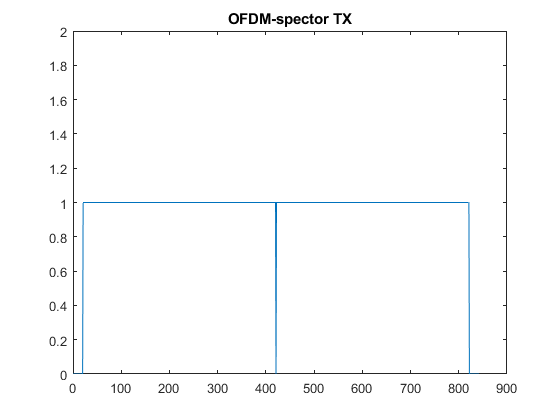


% OFDM модуляция
[ofdmSymbCp, ofdmSpectorTx, control] = ofdmModulator(qpskComplex);
plot(abs(ofdmSpectorTx));
ylim([0, 2]);
title('OFDM-spector TX');

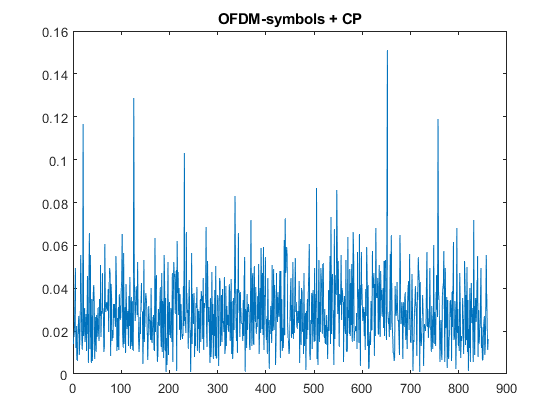


plot(abs(ofdmSymbCp));
%ylim([0, 0.5]);
title('OFDM-symbols + CP');

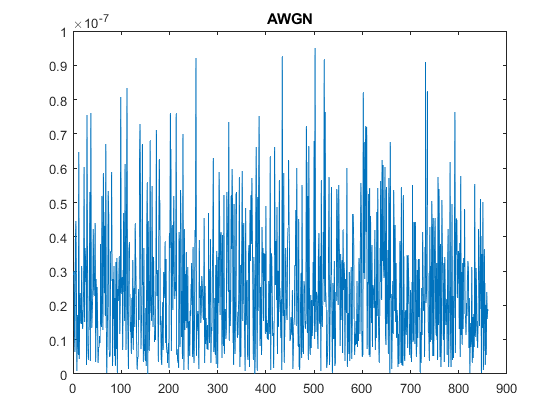


% Канал
[awgn, summBeamsNoise, summBeamsNoiseDoppler] = channel(ofdmSymbCp);
plot(abs(awgn));
title('AWGN');

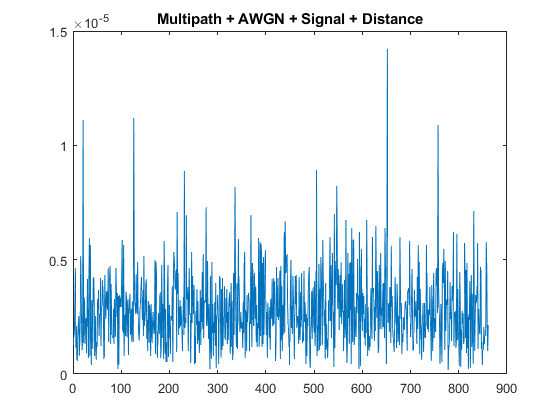


plot(abs(summBeamsNoise));
title('Multipath + AWGN + Signal + Distance');

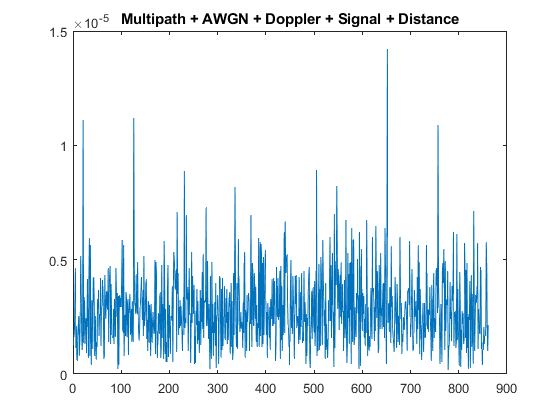


plot(abs(summBeamsNoiseDoppler));
title('Multipath + AWGN + Doppler + Signal + Distance');

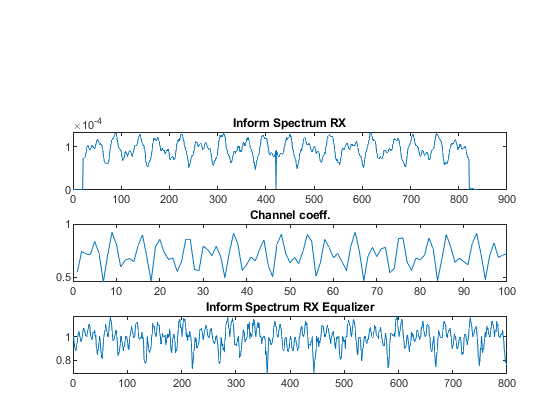

% OFDM демодуляция
[modSymbolRx] = ofdmDemodulator(summBeamsNoise, control);

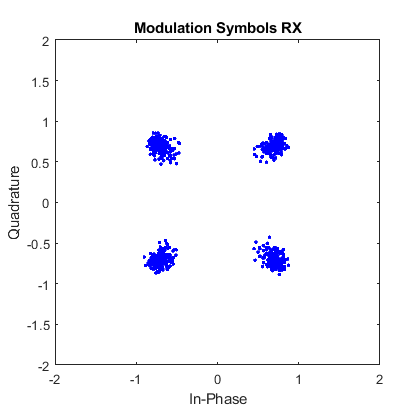

scatterplot(modSymbolRx);
xlim([-2, 2]);
ylim([-2, 2]);
title('Modulation Symbols RX');

% QPSK демодуляция
[qpskBits] = qpskDecoder(modSymbolRx);

% Interleaving
[interleavingDecoderBits] = interleavingDecoder(qpskBits, interleavingPattern);

% Convolutional decoder
[deConvBitArray] = ConvDecoder(interleavingDecoderBits);

% Измерение SNR
MSE = sum(abs(modSymbolRx - qpskComplex) .^ 2) / length(qpskComplex);
SNR = 10*log10(1 / MSE);
disp(SNR);

   18.9822



% check arrays
ber_count = 0;
for i = 1 : length(bitArray)
    if bitArray(i) ~= deConvBitArray(i)
        ber_count = ber_count + 1;
    end
end
BER = ber_count / length(bitArray);
disp(BER);

     0

